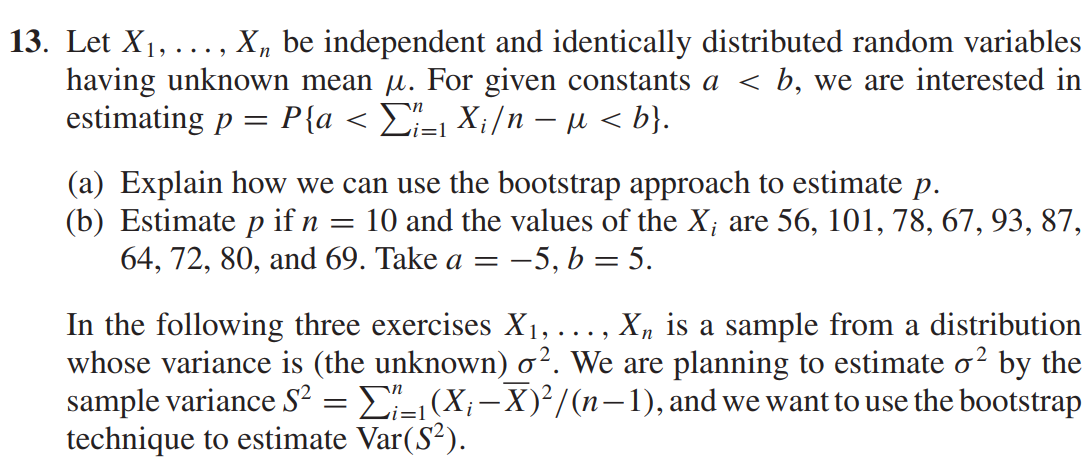

a) sample with r datasets using sampling with replacements from variables

Xi. Then calculate the mean for each of them. Calculate the estimte of  mu as mean as replicate means.

We substract mu from means and check how many are within the range ]a,b[.

clc;clear;

n = 10;
X = [56,101,78,67,93,87,64,72,80,69];
a = -5;b = 5;
r =100;
for i = 1:r
y(i,:) = datasample(X, 10);
end


mu = mean(y,2);

delta = (mean(X)-mu);

sum(delta>a & delta<b)/r

ans =    0.790000000000000


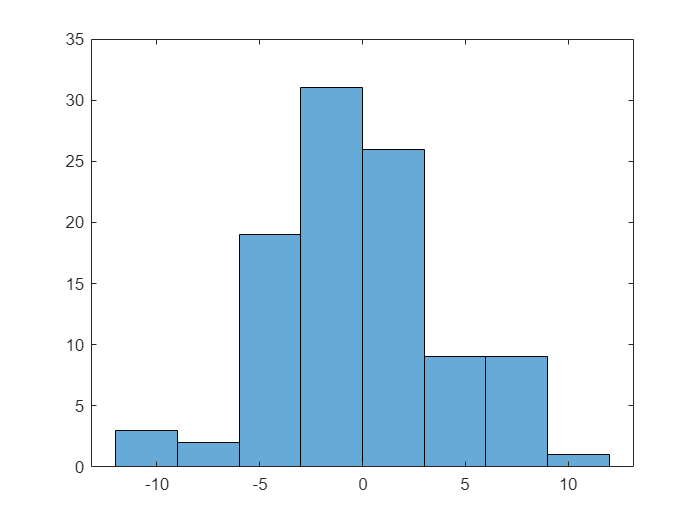

histogram(delta)

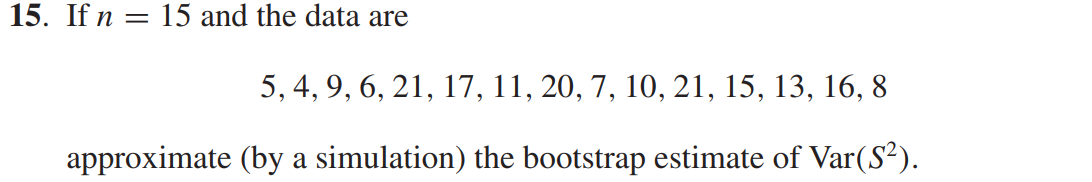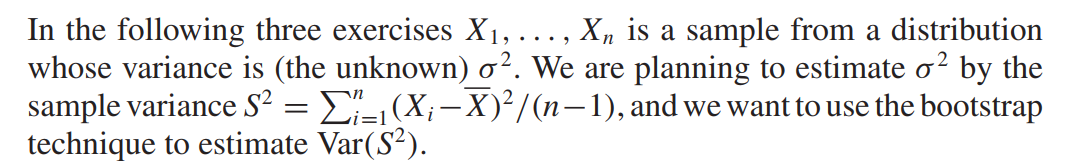

clc;clear;
n = 15;
X = [5,4,9,6,21,17,11,20,7,10,21,15,13,16,8];
r = 100;

for i = 1:r
y = datasample(X, n);
S2(i) = var(y);
end
var(S2)

ans =   81.886068036372805


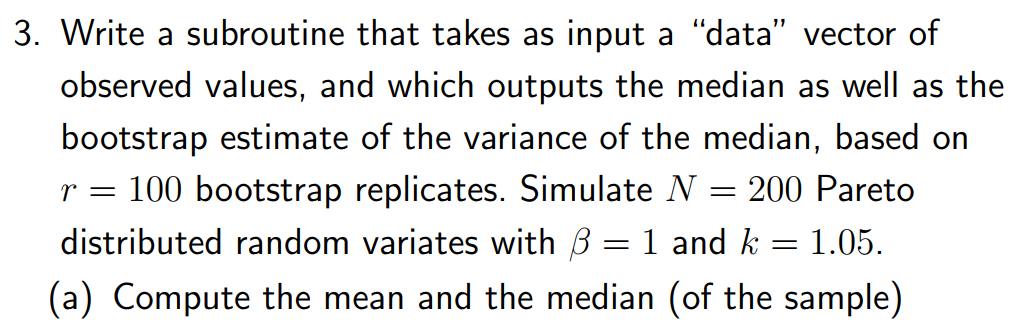

%%
clc;clear;
rng(3);
r = 100;
N = 200;

beta = 1; k =1.05;

%f_Pareto = @(x) k*beta^k./(x.^(k+1));
%F_Pareto = @(x) 1-(beta./x).^k;

U = rand(N,1); %array of rands
X_Pareto = beta*(U.^(-1/k));

%%a
mean(X_Pareto)

ans =    3.667064669805733


median(X_Pareto)

ans =    1.999714016971488


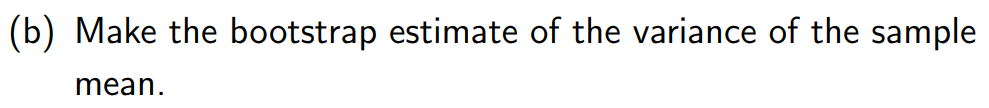

for i = 1:r
y(i,:) = datasample(X_Pareto, N);
end

mean_e = mean(y,2);
var(mean_e)

ans =    0.105753332156850


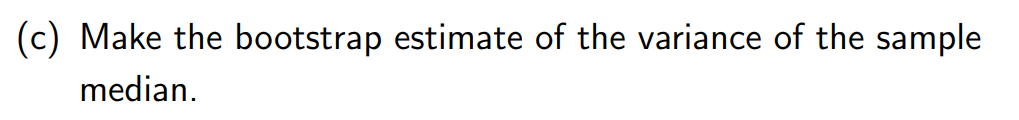

meadian_e = median(y,2);
var(meadian_e)

ans =    0.018606598550767
